## 1. gyakorlat

#### 1. Feladat

a) Határozzuk meg az 


$$A=\left[\begin{array}{rrr}
1 & -1 & -1 \\
-1 & 1 & -1 \\
-1 & -1 & 1
\end{array}\right] $$
 

mátrix sajátértékeit és sajátvektorait!

b) Diagonalizálható-e a mátrix? Mennyi a sajátértékek algebrai és geometriai multiplicitása? Mik a sajátalterek?* (Szimmetrikus mátrix, ortogonális mátrixszal diagonalizálható, vannak többszörös sajátértékei.)*

c) Készítsük el MATLABban is a sajátvektorokat, sajátértékeket. Hogyan tudjuk ellenőrizni, hogy a kétdimenziós sajátalterek azonosak (a papíron és a MATLAB által számolt alterek)?

% a)
A = [1, -1, -1; -1, 1, -1; -1, -1, 1]
[V, D] = eig(A)

% b)

% c) 


#### 2. Feladat

a) Határozzuk meg a síkon az origó körüli $\varphi$ szöggel (óramutató járásával ellentétesen) való forgatás mátrixának sajátértékeit és sajátvektorait!

b) Diagonalizálható-e a mátrix? Mennyi a sajátértékek algebrai és geometriai multiplicitása? Mik a sajátalterek? *(Ortogonális mátrix, unitér mátrixszal diagonalizálható, komplex sajátértékei vannak.)*

Csúszkával szemléltetve:

phi = 3.9

phi = 3.9000

T=[cos(phi), -sin(phi); sin(phi), cos(phi)]

T =    -0.7259    0.6878
   -0.6878   -0.7259


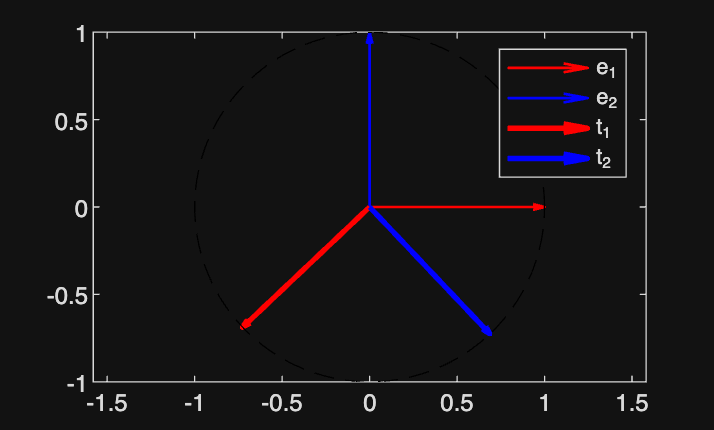


quiver(0,0,1,0, 1, 'r-', 'LineWidth',1)
hold on
quiver(0,0,0,1, 1, 'b-','LineWidth',1)
quiver(0,0,T(1,1),T(2,1), 1, 'r-', 'LineWidth',2)
quiver(0,0,T(1,2),T(2,2), 1, 'b-', 'LineWidth',2)
t=linspace(0,2*pi,100);
plot(cos(t),sin(t),'k--')
axis([-1,1,-1,1])
legend('e_1','e_2', 't_1', 't_2')
axis equal
hold off

% Megoldás phi=pi/3-ra:


### Karakterisztikus polinom, sajátértékek, sajátvektorok

`poly(x) :` az $(x-x_1)(x-x_2) \cdots (x-x_n)$ polinom együtthatói

`poly(A) :` az $A$ mátrix karakterisztikus polinomjának együtthatói

`roots(poly(A)) : az `$A$ mátrix sajátértékei

`eig(A) :` `az `$A$ mátrix sajátértékei

`[V,D] = eig(A) : Az `$A$-t diagonalizáló $V$mátrix és a sajátértékeket tartalmazó $D$ diagonális mátrix. Ha $A$ diagonalizálható: $A=V D V^{-1}$.

`V*D/V :` osztás a $V$ mátrixszal = jobbról szorzás a $V$ mátrix inverzével!

#### 3. Feladat

Ellenőrizzük, hogy az eig utasítással kapott $V$ mátrix tényleg diagonalizálja az $A$ mátrixot!

% Megoldás
gyak01_feladat3

lambda = 1.0e+05 *

    0.0000
    0.0002
    0.0017
    0.0022
    0.0041
    0.0065
    0.0090
    0.0095
    0.0137
    0.0146
    0.0229
    0.0251
    0.0280
    0.0340
    0.0406


p = 1.0e+304 *

    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000


Error using roots (line 27)
Input to ROOTS must not contain NaN or Inf.

Error in gyak01_feladat3 (line 8)
r = sort(roots(p))
^^^^^^^^^^^^^^^^^^

#### 4. Feladat (HF)

Határozzuk meg az 1. előadáson és 1. gyakorlaton megadott mátrixok sajátértékeit és sajátvektorait a Matlab segítségével. Miért kaptunk néhol más eredményt?

`A=[-2,0,0; -5,-2,-5; 5,0,3];`

`A=[4,0,0; 8,4,8; 0,0,4];`

`A=[0,-1; 1,0];`

% Megoldás
